## **CYKLY SPALOVACÍCH TURBÍN - HUMPREY CYKLUS**

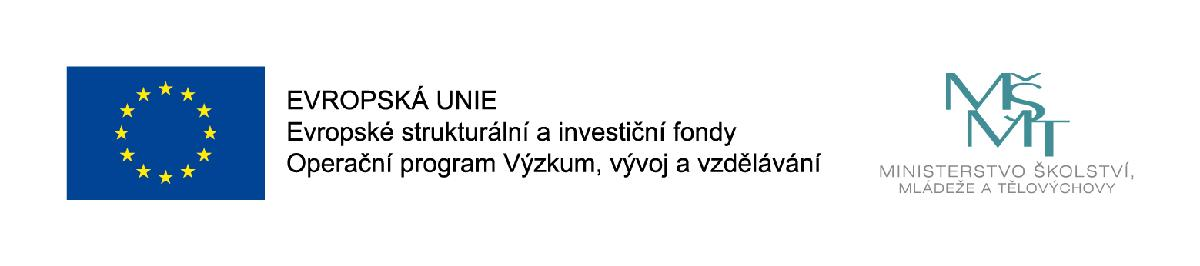

#### prof. Ing. Josef ŠTĚTINA, Ph.D. / Vysoké učení technické v Brně

#### email: [josef.stetina@vutbr.cz](mailto:josef.stetina@vutbr.cz)

#### www: [http://termomechanika.online/](http://termomechanika.online/)

Humpreyův cyklus je v podstatě Ottův cyklus s kompresí. Podle tohoto pracovního cyklu pracovala *plynová **Holzwarthova* *turbina* (1908) se spalo­váním při konstantním objemu a nyní *tryskové motory *se spalováním za stálého objemu. Pochod obou zařízení je přetržitý, a proto se nazývají *motory pulsační.*

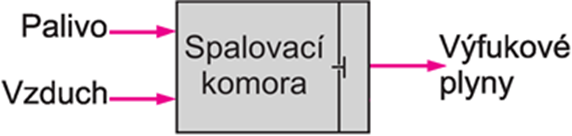

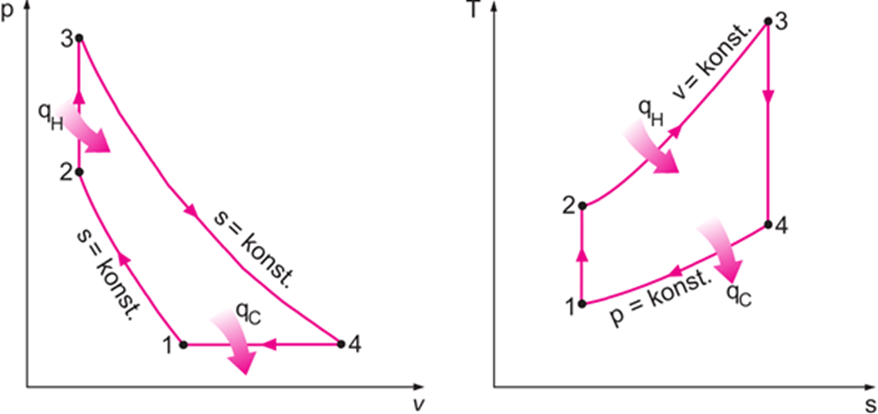

Přívedené a odvedené teplo:


$$${Q_H} = m{c_V}({T_3} - {T_2})$$$
                            
$$${Q_C} = m{c_p}({T_1} - {T_4})$$$


Výpočet termické účinnosti:


$$\[{\eta _t} = 1{\kern 1pt}  - \frac{{\left| {{Q_C}} \right|}}{{{Q_H}}} = 1{\kern 1pt}  - \frac{{m{c_p}({T_4}{\kern 1pt}  - {\kern 1pt} {T_1})}}{{m{c_V}({T_3}{\kern 1pt}  - {\kern 1pt} {T_2})}} = ... = 1{\kern 1pt}  - \frac{{\kappa ({\psi ^{1/\kappa }} - {\kern 1pt} 1)}}{{{\varepsilon ^{\kappa  - 1}}(\Psi {\kern 1pt}  - {\kern 1pt} 1)}} = 1{\kern 1pt}  - {\varepsilon _p}^{\kappa  - 1}\frac{{\kappa ({\psi ^{1/\kappa }} - {\kern 1pt} 1)}}{{(\Psi {\kern 1pt}  - {\kern 1pt} 1)}}\]$$


# 
$$${\eta _t} = f\left( {\kappa ,\;\varepsilon } \right)$$$


Účinnost zážehového cyklu roste se stoupajícím kompresním poměrem. Podle tohoto výrazu závisí termická účinnost též na poissonově konstantě*. *Účinnost zážehového cyklu roste tedy s rostoucí hodnotou poissonově konstantě*, *tj. s menším počtem atomů v molekule plynu.

Jak bylo již dříve uvedeno, je zvyšování termické účinnosti zážehového cyklu zvětšováním kompresního poměru je omezeno teplotou vznícení nasáté směsi. Pří­pustný stupeň komprese e se tudíž pro různá paliva značně liší.

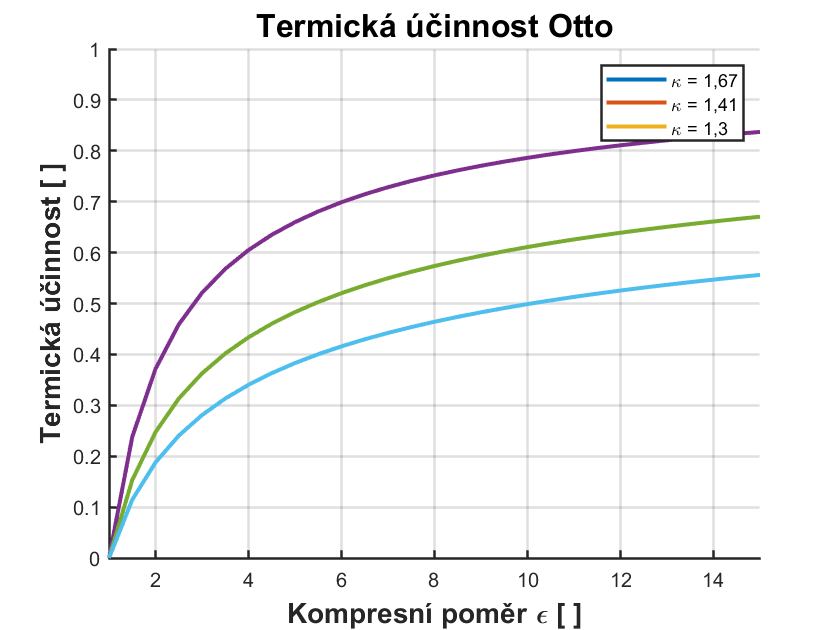

subplot(1,1,1);
i = 1;
eps_v = zeros(1, 29);
eta_t_1 = zeros(1, 29);
eta_t_2 = zeros(1, 29);
eta_t_3 = zeros(1, 29);
for eps=1:0.5:15
    eps_v(i) = eps;
    eta_t_1(i) = 1-(1/eps)^(kappaB(1)-1);
    eta_t_2(i) = 1-(1/eps)^(kappaB(2)-1);
    eta_t_3(i) = 1-(1/eps)^(kappaB(3)-1);
    i = i + 1;
end
title('Termická účinnost Otto','FontSize', 16 , 'FontName', 'Helvetica','FontWeight','bold');
xlabel('Kompresní poměr \epsilon [ ]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
ylabel('Termická účinnost [ ]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
xlim([1 15]);
ylim([0 1]);
set(gca, 'linewidth',1.2);
hold on;
plot(eps_v,eta_t_1,'-','linewidth',2);
plot(eps_v,eta_t_2,'-','linewidth',2);
plot(eps_v,eta_t_3,'-','linewidth',2);
grid on;
legend('\kappa = 1,67','\kappa = 1,41','\kappa = 1,3')
hold off;

# $${\eta _t}$$lze zvyšovat kompresním poměrem

### Příklad

Ideální cyklus plynové turbíny pracuje s přívodem tepla při konstantním objemu (Humpreyův cyklus). Maximální teplota před turbínou je 1000 °C a teplota nasávaného vzduchu je 24 °C a tlak 1001 hPa. Tlakový poměr kompresoru je 6. Vypočítejte měrnou práci cyklu a měrné přivedené  a odvedené teplo, dále termickou účinnost a výkon turbíny pokud je množství nasávaného vzduchu 2 kg/s. Pracovní látka má vlastnosti vzduchu (r = 287 J/kgK, kappa = 1,40). Nakreslete p-v a T-s diagram.

p1 : 98.0 kPa T1 :  293.1 K 


p2 : 784.0 kPa T2 :  531.0 K 


p3 : 784.0 kPa T3 :  1173.2 K 


p4 : 98.0 kPa T4 :  647.6 K 


Přivedené měrné teplo : 645.0 [kJ/kg]


Odvedené měrné teplo  : -356.1 [kJ/kg]


Měrní práce cyklu     : 288.9 [kJ/kg]


Výkon turbíny         : 1444.7 [kW]


Termická účinnost     : 0.448


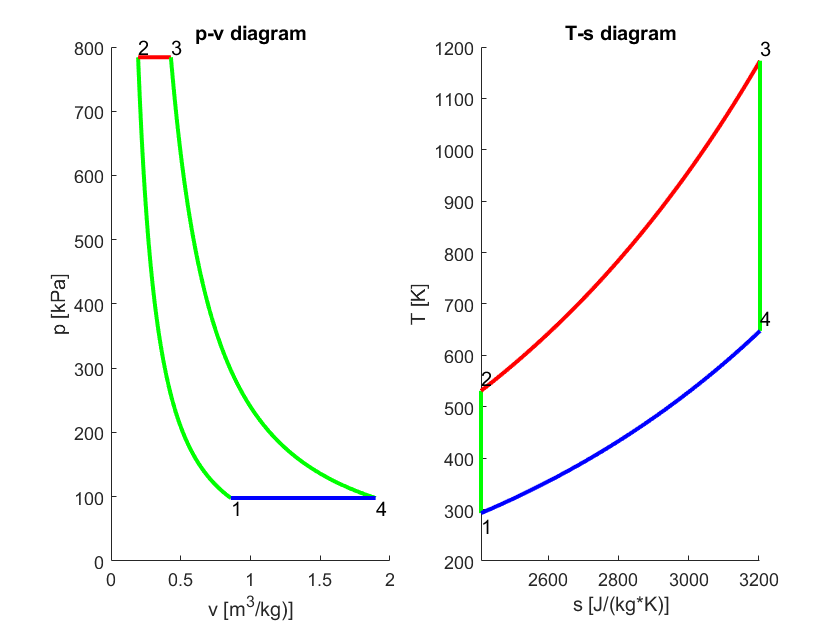

clear all;

p1hPa  = 1001.0; % [hPa] tlak nasávaného vzduchu
mdot   = 2.0;   % [kg/s] hmotnostní tok vzduchu turbínou
t1C   = 24;     % [C]  teplota nasávaného vzduchu
epsp  = 6;      % [-]  tlakový poměr
t3C   = 1000.0;  % [C]  maximální teplota
r = 287.0;      % [J/kgK] plynová konstanta
kappa = 1.40;   %
%% 
cv = 1/(kappa-1) * r;
cp = cv * kappa;
%% Bod 1
T1 = C2K(t1C);
p1 = hPa2Pa(p1hPa);
%% Bod 2
p2 = p1 * epsp;
T2 = T1*(epsp)^((kappa-1)/kappa);
v2 = r * T2/p2;
%% Bod 3
T3 = C2K(t3C);
v3 = v2;
p3 = r * T3/v3;
%% Bod 4
p4 = p1;
T4 = T3*(p4/p3)^((kappa-1)/kappa);
%% Měrná práce a tepla
qh = cv * (T3-T2);
qc = cp * (T1-T4);
ao =  qh - abs(qc);

Pt = mdot * ao;

etat = ao / qh;

%% výstupní data
clc;
fprintf('p1 : %.1f kPa T1 :  %.1f K \n',Pa2kPa(p1),  T1);
fprintf('p2 : %.1f kPa T2 :  %.1f K \n',Pa2kPa(p2),  T2);
fprintf('p3 : %.1f kPa T3 :  %.1f K \n',Pa2kPa(p3),  T3);
fprintf('p4 : %.1f kPa T4 :  %.1f K \n',Pa2kPa(p4),  T4);
fprintf('Přivedené měrné teplo : %.1f [kJ/kg]\n',J2kJ(qh));
fprintf('Odvedené měrné teplo  : %.1f [kJ/kg]\n',J2kJ(qc));
fprintf('Měrní práce cyklu     : %.1f [kJ/kg]\n',J2kJ(ao));
fprintf('Výkon turbíny         : %.1f [kW]\n',W2kW(Pt));
fprintf('Termická účinnost     : %.3f\n',etat);

Grafy

v1 = r * T1/ p1;
v2 = r * T2/ p2;
v3 = r * T3/ p3;
v4 = r * T4/ p4;

pv1 = linspace(p1,p2,180);
Vv1 = zeros([1,180]);
Tv1 = zeros([1,180]);
Sv1 = zeros([1,180]);

for i=2:180
  Tv1(i) = T1*(pv1(i)/p1)^((kappa-1)/kappa);
  Vv1(i) = r * Tv1(i)/ pv1(i);
  Sv1(i)=cp*log(Tv1(i))-r*log(pv1(i));
end
pv1(1) = p1;
pv1(180) = p2;
Vv1(1) = v1;
Vv1(180) = v2;
Tv1(1) = pv1(1) * Vv1(1) / r;
Sv1(1)= cp*log(Tv1(1))- r*log(pv1(1));

pv2 = linspace(p2,p3,180);
Vv2 = zeros([1,180]);
Tv2 = zeros([1,180]);
Sv2 = zeros([1,180]);
for i=2:180
  Vv2(i)= v2;
  Tv2(i) = pv2(i) * Vv2(i) / r;
  Sv2(i)= cp*log(Tv2(i))- r*log(pv2(i));
end
pv2(1) = p2;
pv2(180) = p3;
Vv2(1) = v2;
Vv2(180) = v3;
Tv2(1) = pv2(1) * Vv2(1) / r;
Sv2(1)= cp*log(Tv2(1))- r*log(pv2(1));

Vv3 = linspace(v3,v4,180);
pv3 = zeros([1,180]);
Tv3 = zeros([1,180]);
for i=2:180
  pv3(i)=p3*v3^kappa/Vv3(i)^kappa;
  Tv3(i) = pv3(i) * Vv3(i) / r;
  Sv3(i)= cp*log(Tv3(i))- r*log(pv3(i));    
end
pv3(1) = p3;
pv3(180) = p4;
Vv3(1) = v3;
Vv3(180) = v4;
Tv3(1) = pv3(1) * Vv3(1) / r;
Sv3(1)= cp*log(Tv3(1))- r*log(pv3(1));    

Vv4 = linspace(v4,v1,180);
pv4 = zeros([1,180]);
Tv4 = zeros([1,180]);
Sv4 = zeros([1,180]);
for i=2:180
  pv4(i)= p1;
  Tv4(i) = pv4(i) * Vv4(i) / r;
  Sv4(i)= cp*log(Tv4(i))- r*log(pv4(i));
end
pv4(1) = p4;
pv4(180) = p1;
Vv4(1) = v4;
Vv4(180) = v1;
Tv4(1) = pv4(1) * Vv4(1) / r;
Sv4(1)= cp*log(Tv4(1))-r*log(pv4(1));

% Vykreslení diagramu
figure;
subplot(1,2,1);
hold on;
plot(Vv1,pv1/1000.0,'g-','linewidth',2);
plot(Vv2,pv2/1000.0,'r-','linewidth',2);
plot(Vv3,pv3/1000.0,'g-','linewidth',2);
plot(Vv4,pv4/1000.0,'b-','linewidth',2);
hold off;
% popis bodů diagramu
text(Vv1(1),pv1(1)/1000.0-16,'1');
text(Vv2(1),pv2(1)/1000.0+16,'2');
text(Vv3(1),pv3(1)/1000.0+16,'3');
text(Vv4(1),pv4(1)/1000.0-16,'4');
% název grafu a popisy os
title('p-v diagram')
xlabel('v [m^3/kg)]')
ylabel('p [kPa]')                     
subplot(1,2,2);
hold on;
plot(Sv1,Tv1,'g-','linewidth',2);
plot(Sv2,Tv2,'r-','linewidth',2);
plot(Sv3,Tv3,'g-','linewidth',2);
plot(Sv4,Tv4,'b-','linewidth',2);
hold off;
% popis bodů diagramu
text(Sv1(1),Tv1(1)-25,'1');
text(Sv2(1),Tv2(1)+25,'2');
text(Sv3(1),Tv3(1)+25,'3');
text(Sv4(1),Tv4(1)+25,'4');
% název grafu a popisy os
title('T-s diagram');
xlabel('s [J/(kg*K)]');
ylabel('T [K]');


### Lokální funkce 

Poissonova konstanta

function [result] = kappaB(atom)
              switch atom
                  case 1  
                    result = 1.67;
                  case 2
                    result = 1.41;
                  case 3  
                    result = 1.3;  
                  otherwise
                    result = 1.3;  
              end     
end

Univerzální plynová konstanta

function [result] = Rm
   result = 8314.3;              
end   

Převádí teplotu ve stupních Celsia na Kelvíny

function [K] = C2K(C)
K = C+273.15;
end

Převádí hektopascaly na Pascaly

function [Pa] = hPa2Pa(hPa)
Pa = hPa*100;
end 

Převod litrů

function [m3] = l2m3(l)
m3 = l*.001;
end

Převod Pascalů

function [kPa] = Pa2kPa(Pa)
kPa = Pa/1000;
end

Převod Watů

function [kW] = W2kW(W)
kW = W/1000;
end

Převod

function [mm] = m2mm(m)
mm = m*1000;
end

Převod

function [MPa] = Pa2MPa(Pa)
MPa = Pa*0.000001;
end

function [kJ] = J2kJ(J)
kJ = J/1000;
end